# ANALYSIS OF LIGHT RESPONSES IN GLIA IN SMH MUTANT

## STEP1 SET PATHS AND LOAD ALL DATA INTO ONE CELL ARRAY-------------------------------------------------------------------------------------------

set path to codes

addpath(genpath('\\forskning.it.ntnu.no\ntnu\mh\ikom\jurischyaksi\Nathalie\data\github\DGama_et_al_CR_2024'))

set the path for the 2p data and the number of cell data

cfg.pathData='\\forskning.it.ntnu.no\ntnu\mh\ikom\jurischyaksi\Nathalie\other\manuscript\in preparation\DGama_brainphysiology_smh\2p_glia\data_newROI\';

load the data into few matrix

[ctrlON,mutON,time]=nj_load2pGliadata_v2(cfg);

calculate the number of dataset

numCTRL=size(ctrlON,1)-1

numCTRL = 10

numMUT=size(mutON,1)-1

numMUT = 11

## STEP2 SET SOME PARAMETERS FOR THE PLOTS----------------------------------------------------------------------------------------------------------------

close all
clear cfg

enter some parameters for the plots into one variable called cfg

cfg.MutID='SMH' %enter the name of your mutant 'ELIPSA', this is for the title

cfg = struct with fields:
    MutID: 'SMH'


cfg.Mutcolor='m' %enter the color you want for your mutantd display, 'm'= magenta, 'c'=cyan

cfg = struct with fields:
       MutID: 'SMH'
    Mutcolor: 'm'


cfg.numCTRL=numCTRL;
cfg.numMUT=numMUT;
cfg.label=["tel" "mid/hb" "hind"];
cfg.brainRegion=char('Telencephalon','Midbrain/Habenula','Hindbrain');
cfg

cfg = struct with fields:
          MutID: 'SMH'
       Mutcolor: 'm'
        numCTRL: 10
         numMUT: 11
          label: ["tel"    "mid/hb"    "hind"]
    brainRegion: [3×17 char]


## STEP3 PLOT THE AVERAGE RESPONSE TO LIGHT STIMULI IN THE WHOLE BRAIN OR IN SPECIFIC REGIONS----------------------------

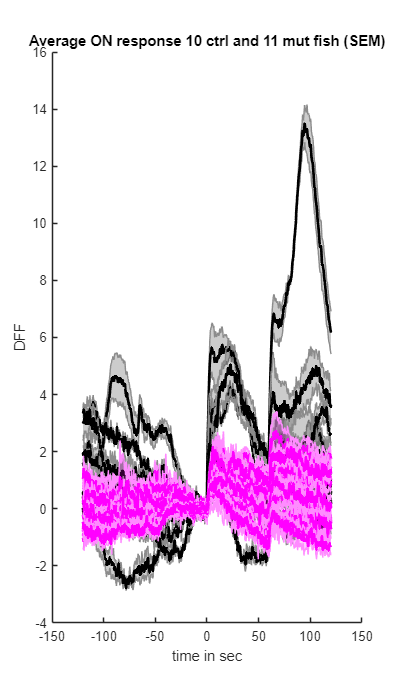

[averageON_ALL]=plot_responseALL_perfish(ctrlON,mutON,time,cfg);

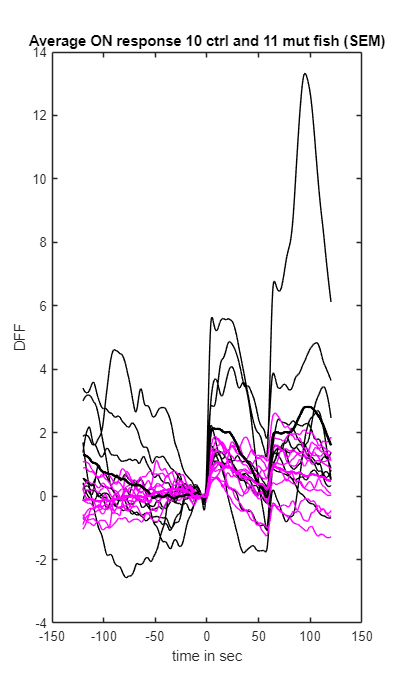

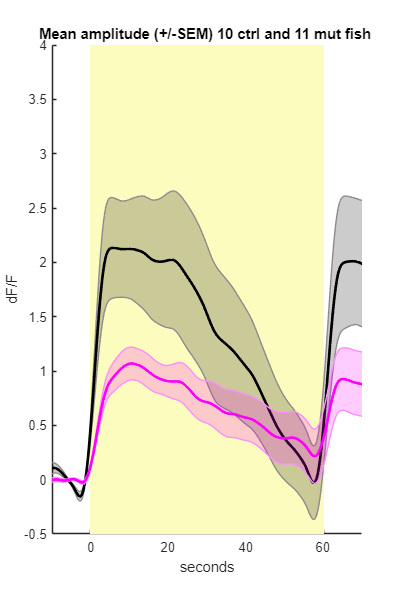

plot_responseALL_perfish2(ctrlON,mutON,time,cfg);

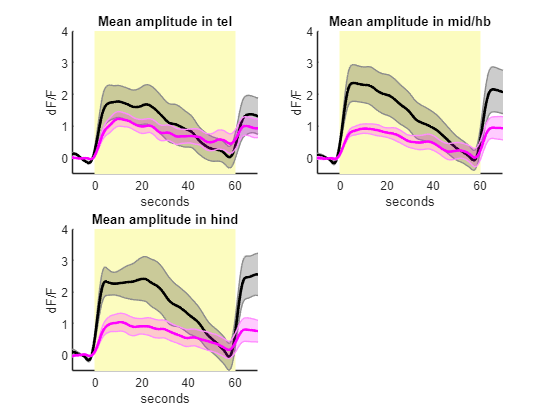

plot_responseALL_perfish3(ctrlON,mutON,time,cfg)

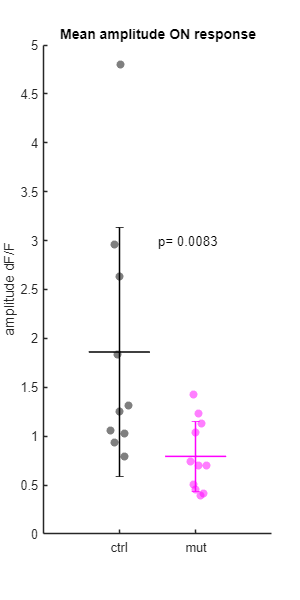

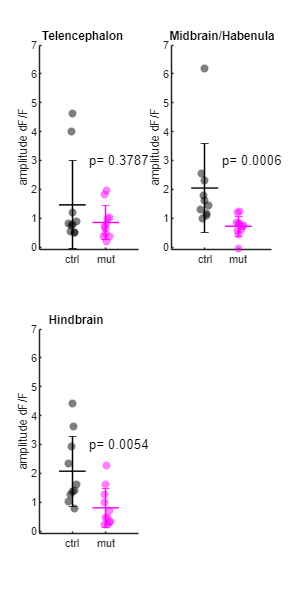

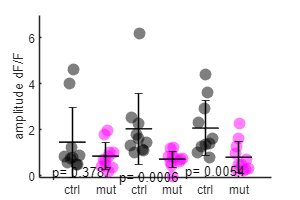

plot_scatterAll(averageON_ALL,ctrlON,mutON, time,cfg)

## STEP4 PLOT THE OVERALL ACTIVITY FOR ALL CTRLS AND MUT AND BRAIN REGIONS-----------------------------------------------------------

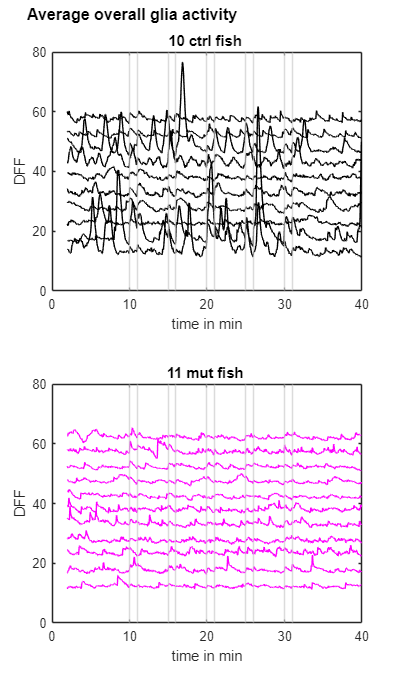

plot_ALL_perfish(ctrlON,mutON,time,cfg)

counter = 1

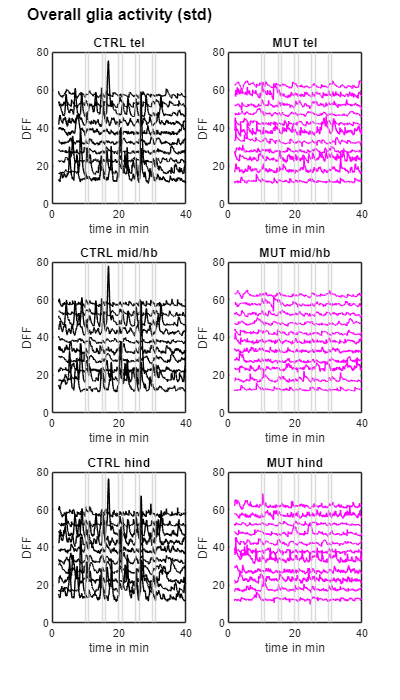

plot_ALL_perfish2(ctrlON,mutON,time,cfg)

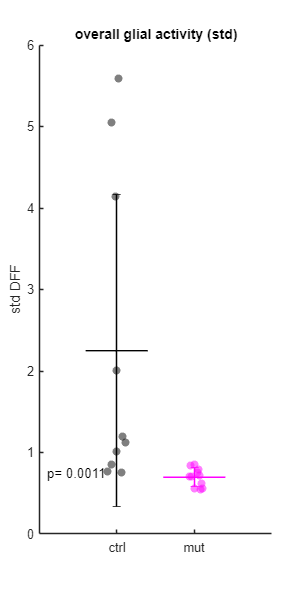

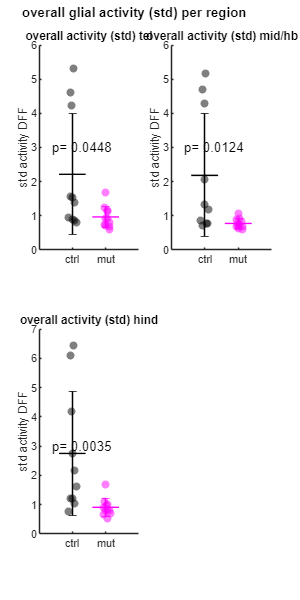

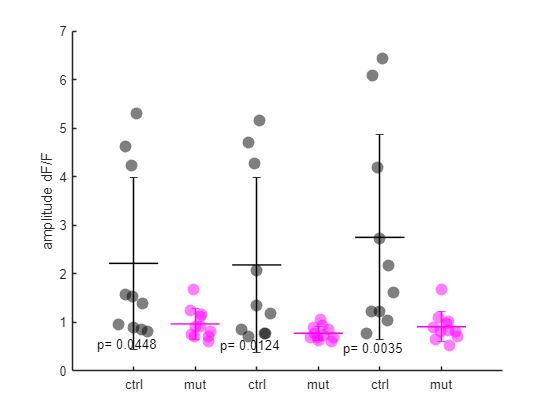

plot_scatter_allfish(ctrlON,mutON,cfg)

## NESTED FUNCTIONS

FUNCTION 1: IMPORT ALL DATA INTO THE LIVE EDITOR SCRIPT

function [ctrlON,mutON,time]=nj_load2pGliadata_v2(cfg)

% STEP 1 LOAD THE RESPONDING CELL DATA
path=cfg.pathData;
cd(path)

% STEP1.1 LOAD THE CTRL DATA INTO ONE CELL ARRAY------------------------------------------

stk_files = dir(fullfile(path, '*ctrl*' ));

% makes a cell array called ctrlON for ctrlON datasets and ctrlOFF for ctrlOFF datasets
% raw one is just the title of the columns in the array
ctrlON=cell(1,3);
ctrlON{1,1}='name'; 
ctrlON{1,2}='averageONresponse'; 
ctrlON{1,3}='averageactivity'; 

% I need a counter so that tehre is no empty rows
countON=2;

for i=1:length(stk_files)
load(stk_files(i).name);
fps=amplitude.cfg.originalfps;
    ctrlON{countON,1}=stk_files(i).name;
    ctrlON{countON,2}=amplitude.DFFstim_meanRegion;
    ctrlON{countON,3}=amplitude.DFF_meanRegion;
    countON=countON+1;

time.stim=amplitude.timestim;
time.overall=amplitude.time;
amplitude=[];
end
stk_files=[];


% STEP1.2 LOAD THE MUTANT DATA INTO ONE CELL ARRAY------------------------------------------

stk_files = dir(fullfile(path, '*mut*' ));

% makes a cell array called mutON for mutON datasets and mutOFF for mutOFF datasets
% raw one is just the title of the columns in the array
mutON=cell(1,3);
mutON{1,1}='name'; 
mutON{1,2}='averageONresponse'; 
mutON{1,3}='averageactivity'; 

% I need a counter so that tehre is no empty rows
countON=2;

for i=1:length(stk_files)
load(stk_files(i).name);
fps=amplitude.cfg.originalfps;
    mutON{countON,1}=stk_files(i).name;
    mutON{countON,2}=amplitude.DFFstim_meanRegion;
    mutON{countON,3}=amplitude.DFF_meanRegion;
    countON=countON+1;
amplitude=[];
end

stk_files=[];

end

FUNCTION 2 PLOT THE AVERAGE DATA FOR ALL ROI PER ANIMAL FOR ALL ANIMALS, NOTE THE DATA IS NOT SMOOTHENES

function [averageON_ALL]=plot_responseALL_perfish(ctrlON,mutON,time,cfg)

figure 
set(gcf,  'Position',[100 100 400 700])

% Average response ON
for i=2:cfg.numCTRL+1  
shadedErrorBar(time.stim,mean(ctrlON{i,2},1),std(ctrlON{i,2},[],1)/sqrt(size(ctrlON{i,2},1)),'lineprops', 'k'), hold on
xlabel('time in sec')
ylabel('DFF')
averageON_ALL.ctrl(i-1,:)=mean(ctrlON{i,2},1);
end
for i=2:cfg.numMUT+1
shadedErrorBar(time.stim,mean(mutON{i,2},1),std(mutON{i,2},[],1)/sqrt(size(mutON{i,2},1)),'lineprops', cfg.Mutcolor), hold on
xlabel('time in sec')
ylabel('DFF')
averageON_ALL.mut(i-1,:)=mean(mutON{i,2},1);
end
title(['Average ON response ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish (SEM)'])
hold off

end

FUNCTION 3: PLOT THE AVERAGE RESPONSE OF ALL FISHES, DATA IS SMOOTHENED

function plot_responseALL_perfish2(ctrlON,mutON,time,cfg)

figure 

set(gcf,  'Position',[100 100 400 700])

% Average response ON
for i=2:cfg.numCTRL+1  
plot(time.stim,smooth(mean(ctrlON{i,2}),0.05,'loess'), 'k'), hold on
xlabel('time in sec')
ylabel('DFF')
averageON_ALL.ctrl(i-1,:)=smooth(mean(ctrlON{i,2}),0.05,'loess');
end
for i=2:cfg.numMUT+1
plot(time.stim,smooth(mean(mutON{i,2}),0.05,'loess'),'Color', cfg.Mutcolor), hold on
xlabel('time in sec')
ylabel('DFF')
averageON_ALL.mut(i-1,:)=smooth(mean(mutON{i,2}),0.05,'loess');
end
plot(time.stim,mean(averageON_ALL.ctrl,1), 'k','LineWidth',2)
plot(time.stim,mean(averageON_ALL.mut,1), 'Color', cfg.Mutcolor,'LineWidth',2)
title(['Average ON response ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish (SEM)'])
hold off


figure 

set(gcf,  'Position',[100 100 400 600])

rectangle('Position',[0 -8 60 70],'FaceColor',[0.99 0.99 0.75], 'EdgeColor',[0.99 0.99 0.75]), hold on
shadedErrorBar(time.stim,mean(averageON_ALL.ctrl,1),std(averageON_ALL.ctrl,0,1)/sqrt(size(averageON_ALL.ctrl,1)),'lineprops', 'k')
shadedErrorBar(time.stim,mean(averageON_ALL.mut,1),std(averageON_ALL.mut,0,1)/sqrt(size(averageON_ALL.mut,1)),'lineprops', cfg.Mutcolor)
title(['Mean amplitude (+/-SEM) ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])
xlim([-10 70])
ylim([-0.5 4])
xlabel('seconds')
ylabel('dF/F')
hold off
end


FUNCTION 4: PLOT MEAN RESPONSE ACCROSS FISH, DATA IS SMOOTHENED

function plot_responseALL_perfish3(ctrlON,mutON,time,cfg)

for k=1:3
% Average response ON
for i=2:cfg.numCTRL+1  
averageON_ALL.ctrl(i-1,:)=smooth(ctrlON{i,2}(k,:),0.05,'loess');
end
for i=2:cfg.numMUT+1
averageON_ALL.mut(i-1,:)=smooth(mutON{i,2}(k,:),0.05,'loess');
end
averageON_ALL.ctrl_BR(k,:,:)=averageON_ALL.ctrl;
averageON_ALL.mut_BR(k,:,:)=averageON_ALL.mut;
averageON_ALL.ctrl=[];
averageON_ALL.mut=[];
end


figure
for i=1:3
    toplotC=squeeze(averageON_ALL.ctrl_BR(i,:,:));
    toplotM=squeeze(averageON_ALL.mut_BR(i,:,:));
subplot (2,2,i)
rectangle('Position',[0 -8 60 70],'FaceColor',[0.99 0.99 0.75], 'EdgeColor',[0.99 0.99 0.75]), hold on
shadedErrorBar(time.stim,mean(toplotC,1),std(toplotC,0,1)/sqrt(size(toplotC,1)),'lineprops', 'k')
shadedErrorBar(time.stim,mean(toplotM,1),std(toplotM,0,1)/sqrt(size(toplotM,1)),'lineprops', cfg.Mutcolor)
title(['Mean amplitude in '  num2str(cfg.label(i))])
xlim([-10 70])
ylim([-0.5 4])
xlabel('seconds')
ylabel('dF/F')
hold off
clear toplotC toplotM
end
end

FUNCTION 5: PLOT SCATTER OF AVERAGE AMPLITUDE FOR 10SEC AFTER LIGHT ON FOR THE WHOLE BRAIN AND INDIVIDUAL ROIS

function plot_scatterAll(averageON_ALL,ctrlON,mutON, time,cfg)

% enter the frames. 
onset=465;%this is time 0
offset=503;% this is for 10sec

figure 
set(gcf,  'Position',[100 100 300 600])

toplotC=averageON_ALL.ctrl(:,onset:offset);
toplotM=averageON_ALL.mut(:,onset:offset);
swarmchart(ones(cfg.numCTRL,1), mean(toplotC,2),'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(mean(toplotC,2)),1,2),'Color','k')
errorbar(1,mean(mean(toplotC,2)), std(mean(toplotC,2),0,1),'Color','k')
swarmchart(2*ones(cfg.numMUT,1), mean(toplotM,2),cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(mean(toplotM,2)),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(mean(toplotM,2)), std(mean(toplotM,2),0,1),'Color',cfg.Mutcolor)
xlim([0 3]), ylim([0 5])
ylabel('amplitude dF/F')
text(1.5,3,['p= '...
    num2str(ranksum(mean(toplotC,2),mean(toplotM,2)),'%.4f')]);
xticks([1 2])
xticklabels({'ctrl','mut'})
title('Mean amplitude ON response')
%clear toplotC toplotM
hold off


figure 
for k=1:3
set(gcf,  'Position',[100 100 300 600])

subplot(2,2,k)
for i=1:cfg.numCTRL 
matrixC(i,:)=mean(ctrlON{i+1,2}(k,:),1);
end
for i=1:cfg.numMUT 
matrixM(i,:)=mean(mutON{i+1,2}(k,:),1);
end
toplotC=matrixC(:,onset:offset);
toplotM=matrixM(:,onset:offset);
swarmchart(ones(cfg.numCTRL,1), mean(toplotC,2),'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(mean(toplotC,2)),1,2),'Color','k')
errorbar(1,mean(mean(toplotC,2)), std(mean(toplotC,2),0,1),'Color','k')
swarmchart(2*ones(cfg.numMUT,1), mean(toplotM,2),cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(mean(toplotM,2)),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(mean(toplotM,2)), std(mean(toplotM,2),0,1),'Color',cfg.Mutcolor)
xlim([0 3]), ylim([-0.1 7])
ylabel('amplitude dF/F')
text(1.5,3,['p= '...
    num2str(ranksum(mean(toplotC,2),mean(toplotM,2)),'%.4f')]);
xticks([1 2])
xticklabels({'ctrl','mut'})
title([cfg.brainRegion(k,:)])
clear toplotC toplotM matrixC matrixM
hold off
end
hold off

figure 
for i=1:3
set(gcf,  'Position',[100 100 300 200])

for k=1:cfg.numCTRL 
matrixC(k,:)=mean(ctrlON{k+1,2}(i,:),1);
end
for k=1:cfg.numMUT 
matrixM(k,:)=mean(mutON{k+1,2}(i,:),1);
end
toplotC=mean(matrixC(:,onset:offset),2);
toplotM=mean(matrixM(:,onset:offset),2);
swarmchart((i-1)+ones(size(toplotC,1),1), mean(toplotC,2,'omitnan'),80,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line((i-1)+[0.8 1.2], repmat(mean(mean(toplotC,2,'omitnan'),'omitnan'),1,2),'Color','k')
errorbar((i-1)+1,mean(mean(toplotC,2,'omitnan'),'omitnan'), std(mean(toplotC,2,'omitnan'),'omitnan'),'Color','k')
swarmchart((i-1)+1.5*ones(size(toplotM,1),1), mean(toplotM,2,'omitnan'),80,'m','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line((i-1)+[1.3 1.7], repmat(mean(mean(toplotM,2,'omitnan'),'omitnan'),1,2),'Color','k')
errorbar((i-1)+1.5,mean(mean(toplotM,2,'omitnan'),'omitnan'), std(mean(toplotM,2,'omitnan'),'omitnan'),'Color','k')
ylabel('amplitude dF/F')
xlim([0.5 4]), ylim([-0.1 7])
text((i-1)+0.7,0.9*min(cat(1,toplotC,toplotM)),['p= '...
    num2str(ranksum(mean(toplotC,2,'omitnan'),mean(toplotM,2,'omitnan')),'%.4f')]);
xticks([1 1.5 2 2.5 3 3.5])
xticklabels({'ctrl','mut','ctrl','mut','ctrl','mut'})
clear toplotC toplotM matrixC matrixM
end
hold off



end

FUNCTION 6: PLOT THE DFF FOR THE WHOLE RECORDING FOR EACH FISH, DATA IS SMOOTHEND

function plot_ALL_perfish(ctrlON,mutON,time,cfg)

figure 
set(gcf,  'Position',[100 100 400 700])
str= {['Average overall glia activity']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',12, 'FontWeight', 'bold', 'LineStyle', 'none');

% Average response ON
subplot(2,1,1)
for i=2:cfg.numCTRL+1  
plot(time.overall/60,smooth(mean(ctrlON{i,3},1),0.005,'loess')+i*5, 'k'), hold on
xlabel('time in min')
ylabel('DFF')
averageON_ALL.ctrl(i-1,:)=smooth(mean(ctrlON{i,3},1),0.005,'loess');
end
ylim([0 80])
title([num2str(cfg.numCTRL) ' ctrl fish '])
xline([10,11,15,16,20,21,25,26,30,31],'Color', [0.8 0.8 0.8],'LineWidth', 0.5)
hold off
subplot(2,1,2)
for i=2:cfg.numMUT+1
plot(time.overall/60,smooth(mean(mutON{i,3},1),0.005,'loess')+i*5,'Color', cfg.Mutcolor), hold on
xlabel('time in min')
ylabel('DFF')
averageON_ALL.mut(i-1,:)=smooth(mean(mutON{i,3},1),0.005,'loess');
end
ylim([0 80])
title([num2str(cfg.numMUT) ' mut fish '])
xline([10,11,15,16,20,21,25,26,30,31],'Color', [0.8 0.8 0.8],'LineWidth', 0.5)
hold off
end

FUNCTION 7: PLOT THE DFF FOR THE WHOLE RECORDING FOR EACH FISH PER BRAIN REGION, DATA IS SMOOTHEND

function plot_ALL_perfish2(ctrlON,mutON,time,cfg)

figure 
set(gcf,  'Position',[100 100 400 700])
str= {['Overall glia activity (std)']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',12, 'FontWeight', 'bold', 'LineStyle', 'none');

counter=1
for k=1:3
% Average response ON
subplot(3,2,counter)
for i=2:cfg.numCTRL+1  
plot(time.overall/60,smooth(ctrlON{i,3}(k,:),0.005,'loess')+i*5, 'k'), hold on
xlabel('time in min')
ylabel('DFF')
end
ylim([0 80])
title(['CTRL ' num2str(cfg.label(k))])
xline([10,11,15,16,20,21,25,26,30,31],'Color', [0.8 0.8 0.8],'LineWidth', 0.5)
hold off
counter=counter+1;
subplot(3,2,counter)
for i=2:cfg.numMUT+1
plot(time.overall/60,smooth(mutON{i,3}(k,:),0.005,'loess')+i*5,'Color', cfg.Mutcolor), hold on
xlabel('time in min')
ylabel('DFF')
end
ylim([0 80])
title(['MUT ' num2str(cfg.label(k))])
xline([10,11,15,16,20,21,25,26,30,31],'Color', [0.8 0.8 0.8],'LineWidth', 0.5)
hold off
counter=counter+1;
end
end

FUNCTION 8: PLOT SCATTER FOR STD OF DFF FOR THE ENTIRE BRAIN AND BRAIN REGION, DATA IS SMOOTHEEND

function plot_scatter_allfish(ctrlON,mutON,cfg)

% plot standard deviation of glial activity per fish for the entire bain
%smoothen the data
for i=1:cfg.numCTRL
    data=smooth(mean(ctrlON{1+i,3},1),0.005,'loess');
    dataCTRL(i,:)=data.';
end
%
figure, 
for i=1:cfg.numMUT
    data=smooth(mean(mutON{1+i,3},1),0.005,'loess');
    dataMUT(i,:)=data.';
end


figure
set(gcf,  'Position',[100 100 300 600])

toplotC=std(dataCTRL,0,2).';
toplotM=std(dataMUT,0,2).';

swarmchart(ones(length(toplotC),1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(toplotC,2),1,2),'Color','k')
errorbar(1,mean(toplotC,2), std(toplotC),'Color','k')
swarmchart(2*ones(cfg.numMUT,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(toplotM,2),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(toplotM,2), std(toplotM),'Color',cfg.Mutcolor)
xlim([0 3]), %ylim([-0.5 Inf])
ylabel('std DFF')
text(0.1,min(toplotC),['p= '...
      num2str(ranksum(toplotC,toplotM),'%.4f')]);
xticks([1 2])
xticklabels({'ctrl','mut'})
title('overall glial activity (std)')
%clear toplotC toplotM
hold off

% plot standard deviation of glial activity per fish for the entire bain
%smoothen the data
for k=1:3
for i=1:cfg.numCTRL
matCTRLs(k,i)=std(smooth(ctrlON{1+i,3}(k,:),0.005,'loess'),0,1);
end
for i=1:cfg.numMUT
matMUTs(k,i)=std(smooth(mutON{1+i,3}(k,:),0.005,'loess'),0,1);
end
end

figure 
set(gcf,  'Position',[100 100 300 600])
str= {['overall glial activity (std) per region']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',10, 'FontWeight', 'bold', 'LineStyle', 'none');

for k=1:3
toplotC=matCTRLs(k,:);
toplotM=matMUTs(k,:);
subplot(2,2,k)
swarmchart(ones(length(toplotC),1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(toplotC,2),1,2),'Color','k')
errorbar(1,mean(toplotC,2), std(toplotC,0,2),'Color','k')
swarmchart(2*ones(cfg.numMUT,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(toplotM,2),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(toplotM,2), std(toplotM,0,2),'Color',cfg.Mutcolor)
xlim([0 3]), %ylim([-2 Inf])
ylabel('std activity DFF')
text(0.4,3,['p= '...
     num2str(ranksum(toplotC,toplotM),'%.4f')]);
xticks([1 2])
xticklabels({'ctrl','mut'})
title(['overall activity (std) ' num2str(cfg.label(k))])
%clear toplotC toplotM
hold off
end

figure 
for i=1:3
toplotC=matCTRLs(i,:);
toplotM=matMUTs(i,:);
swarmchart((i-1)+ones(size(toplotC,2),1), toplotC,80,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line((i-1)+[0.8 1.2], repmat(mean(toplotC,2),1,2),'Color','k')
errorbar((i-1)+1,mean(toplotC,2), std(toplotC,0,2),'Color','k')
swarmchart((i-1)+1.5*ones(cfg.numMUT,1), toplotM, 80 ,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line((i-1)+[1.3 1.7], repmat(mean(toplotM,2),1,2),'Color',cfg.Mutcolor)
errorbar((i-1)+1.5,mean(toplotM,2), std(toplotM,0,2),'Color',cfg.Mutcolor)
ylabel('amplitude dF/F')
%xlim([0.5 4]), ylim([-0.1 7])
text((i-1)+0.7,0.9*min(cat(2,toplotC,toplotM)),['p= '...
    num2str(ranksum(toplotC,toplotM),'%.4f')]);
xticks([1 1.5 2 2.5 3 3.5])
xticklabels({'ctrl','mut','ctrl','mut','ctrl','mut'})
clear toplotC toplotM matrixC matrixM
end
hold off

end